# Make a Feature Table

Lily Jiang

Neurotechnology, Brains and Machines 2023 (shell code my Sam Michalka)

This notebook will help you write functions to extract features from your EMG data and put them into a feature table. It is valuable to put this feature extraction process into a function so that you can be sure to run the same processes on your train and test data.

First, load the data you want to work with. This code will expect that you have data in a 3 dimension matrix with the dimensions: channels (electrodes)  x  timepoints (measurements in a trial)  x trials (one attempt at rock, paper, or scissors).

load("exampleEMGdata180trial_train.mat");
%load("exampleEMGdata120trial_test.mat")
% load("anotherDay.mat");

Now, extract the features and put them into a variable. The code to do this will be in a function below (or you can move it into a separate function that is in the same folder).

We will make a list of the names of features to include.

includedFeatures = {'var','rms','mav','wl','stdev','mean'};

Then extract those features. This code extracts the features for each channel separately unless you write an exception to this rule.

feature_table = extractFeatures(dataChTimeTr,includedFeatures,Fs);

Let's make a histogram of each feature type for one channel.

bins_for_hist = 0:10^7:10^9;

figure;
hold on;
histogram(table2array(feature_table(find(labels == 1), "var_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 2), "var_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 3), "var_Ch1")), 'BinEdges', bins_for_hist);
legend(string(["rock","paper","scissors"]));
title('Variance, Channel 1');
hold off;

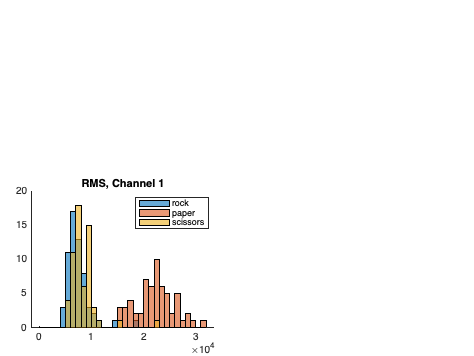

bins_for_hist = 0:10^3:3.25*10^4;

figure;
hold on;
histogram(table2array(feature_table(find(labels == 1), "rms_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 2), "rms_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 3), "rms_Ch1")), 'BinEdges', bins_for_hist);
legend(string(["rock","paper","scissors"]));
title('RMS, Channel 1');
hold off;

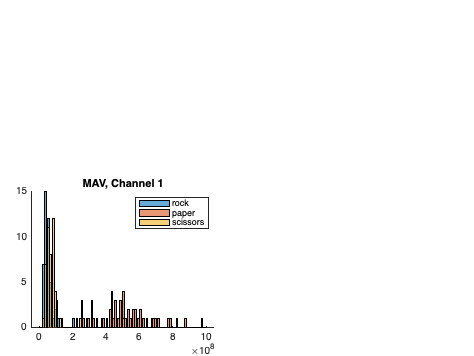

bins_for_hist = 0:10^7:10^9;

figure;
hold on;
histogram(table2array(feature_table(find(labels == 1), "mav_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 2), "mav_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 3), "mav_Ch1")), 'BinEdges', bins_for_hist);
legend(string(["rock","paper","scissors"]));
title('MAV, Channel 1');
hold off;

bins_for_hist = 0:500:1.6*10^4;

figure;
hold on;
histogram(table2array(feature_table(find(labels == 1), "wl_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 2), "wl_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 3), "wl_Ch1")), 'BinEdges', bins_for_hist);
legend(string(["rock","paper","scissors"]));
title('Wavelength, Channel 1');
hold off;

bins_for_hist = 0:500:3.5*10^4;

figure;
hold on;
histogram(table2array(feature_table(find(labels == 1), "stdev_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 2), "stdev_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 3), "stdev_Ch1")), 'BinEdges', bins_for_hist);
legend(string(["rock","paper","scissors"]));
title('St Dev, Channel 1');
hold off;

bins_for_hist = -1500:50:600;

figure;
hold on;
histogram(table2array(feature_table(find(labels == 1), "mean_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 2), "mean_Ch1")), 'BinEdges', bins_for_hist);
histogram(table2array(feature_table(find(labels == 3), "mean_Ch1")), 'BinEdges', bins_for_hist);
legend(string(["rock","paper","scissors"]));
title('Mean, Channel 1');
hold off;

Save your features in a .mat file so you can load them later to do ML without recalculating them.

Change these file names!

save("latest_feature_table.mat","feature_table","labels");
% save("train_feature_table.mat","feature_table","labels");
% save("test_feature_table.mat","feature_table","labels");
% save("newperson_feature_table.mat","feature_table","labels");
% save("another_day_feature_table.mat", "feature_table", "labels");


# Feature extraction code

This is where the magic happens. It takes in your data and outputs a table of features with labels.

- Variance

- RMS (root mean square)

- MAV (Mean absolute value)

function [feature_table] = extractFeatures(dataChTimeTr,includedFeatures, Fs)
    
    % List of channels to include (can change to only use some)
    includedChannels = 1:size(dataChTimeTr,1);
    
    % Empty feature table
    feature_table = table();

    
    for f = 1:length(includedFeatures)

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Calcuate feature values for 
        % fvalues should have rows = number of trials
        % usually fvales will have coluns = number of channels (but not if
        % it is some comparison between channels)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        N = size(dataChTimeTr, 2);

        % Check the name of each feature and hop down to that part of the
        % code ("case" is like... in the case that it is this thing.. do
        % this code)
        switch includedFeatures{f}

            % Variance  
            % variance represents the average squared deviation of the
            % signal from the mean. In this case, the signal is all of the
            % timepoints for a single channel and trial.
            %(fvalues = trials x channels)
            case 'var'
                fvalues = squeeze(var(dataChTimeTr,0,2))';
              
            case 'rms'
                fvalues = squeeze(sqrt((1/N) * sum(dataChTimeTr.^2, 2)))';

            case 'mav'
                fvalues = (1/N) * squeeze(sum(abs(dataChTimeTr.^2), 2))';

            case 'wl'
                fvalues = (1/N) * squeeze(sum(abs(diff(dataChTimeTr, 1, 2)), 2))';

            case 'stdev'
                fvalues = squeeze(std(dataChTimeTr,0,2))';

            case 'mean'
                fvalues = (1/N) * squeeze(sum(dataChTimeTr, 2))';

            otherwise
                % If you don't recognize the feature name in the cases
                % above
                disp(strcat('unknown feature: ', includedFeatures{f},', skipping....'))
                break % This breaks out of this round of the for loop, skipping the code below that's in the loop so you don't include this unknown feature
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Put feature values (fvalues) into a table with appropriate names
        % fvalues should have rows = number of trials
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % If there is only one feature, just name it the feature name
        if size(fvalues,2) == 1
            feature_table = [feature_table table(fvalues,...
                'VariableNames',string(strcat(includedFeatures{f})))];
        
        % If the number of features matches the number of included
        % channels, then assume each column is a channel
        elseif size(fvalues,2) == length(includedChannels)
            %Put data into a table with the feature name and channel number
            for  ch = includedChannels
                feature_table = [feature_table table(fvalues(:,ch),...
                    'VariableNames',string(strcat(includedFeatures{f}, '_' ,'Ch',num2str(ch))))]; %#ok<AGROW>
            end
        
        
        else
        % Otherwise, loop through each one and give a number name 
            for  v = 1:size(fvalues,2)
                feature_table = [feature_table table(fvalues(:,v),...
                    'VariableNames',string(strcat(includedFeatures{f}, '_' ,'val',num2str(v))))]; %#ok<AGROW>
            end
        end

    end 

end
